# 1. ZH – Irányítástechnika

#### 2025.06.09.

*Név: Nagy Richard - 25223020*

Egy feladat megoldását a feladat alá készítse el. A megoldás a teljes, futtatható kódot tartalmazza, továbbá a feladatokban szereplő kérdésekre egyértelmű, egész mondatos választ adjon! Az esetleges SIMULINK modellekről és grafikonokról képet illesszen be!

**Beadás: **

- **.mlx, és .slx Simulink fájlok benyújtása is szükséges a CooSpace felületre!**

- **A feladatot többször is be lehet adni, de az utolsónak feltöltött fájlok lesznek értékelve.**

**1. feladat – 15 p**

**a) Határozza meg, majd elemezze az alábbi ábrán látható rendszer *****W***** eredő átviteli függvényét. Adja meg az eredő rendszer jellegét, pólusait, domináns pólusát, időállandóit, stabilitását, továbbá egységugrás bemenet esetén a beállási időt és beállás után a kimenet állandósult értékét. Ez utóbbit számítsa ki analitikusan is a végérték-tétel segítségével!**

$W_1 \left(s\right)=\frac{10}{\left(s+1\right)}$, $W_2 \left(s\right)=\frac{20}{2\left(s+1\right)}$, $W_3 \left(s\right)=\frac{21}{s^2 +15s+54}$

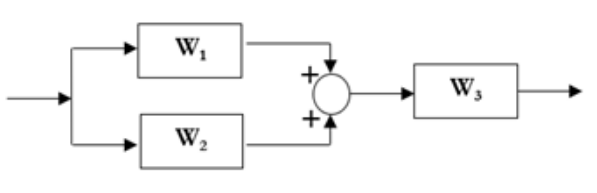

s = zpk('s')


s =
 
  s
 
Continuous-time zero/pole/gain model.
Model Properties


w1 = 10 / (s + 1)


w1 =
 
   10
  -----
  (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


w2 = 20 / (2 * (s + 1))


w2 =
 
   10
  -----
  (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


w3 = 1 / (s * s + 15 * s + 54)


w3 =
 
       1
  -----------
  (s+6) (s+9)
 
Continuous-time zero/pole/gain model.
Model Properties


w = (w1 + w2) * w3


w =
 
       20 (s+1)
  -------------------
  (s+1)^2 (s+6) (s+9)
 
Continuous-time zero/pole/gain model.
Model Properties


w = minreal(w)


w =
 
         20
  -----------------
  (s+6) (s+9) (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties



vegertek = 20 / (6 * 9)

vegertek = 0.3704

vegertek = 1 - vegertek

vegertek = 0.6296

estat = 1 - dcgain(w)

estat = 0.6296


stepinfo(w)

ans = struct with fields:
         RiseTime: 2.2718
    TransientTime: 4.2121
     SettlingTime: 4.2121
      SettlingMin: 0.3336
      SettlingMax: 0.3703
        Overshoot: 0
       Undershoot: 0
             Peak: 0.3703
         PeakTime: 8.5861


pole(w)

ans =    -6.0000
   -9.0000
   -1.0000


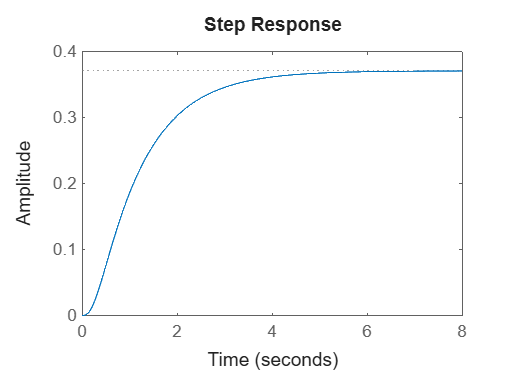


step(w)

dcgain(w)

ans = 0.3704

damp(w)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.00e+00     1.00e+00       1.00e+00         1.00e+00    
 -6.00e+00     1.00e+00       6.00e+00         1.67e-01    
 -9.00e+00     1.00e+00       9.00e+00         1.11e-01    


**Válasz**: 

rendszer jellege - aranyos

polusok = -1, -6, -9

dominans polus = -1

idoallandok = 1, 1/6, 1/9

vegertek tetel = `0.6296`

`statikus hiba = 0.6296`

`stabilitas - veges valaszt ad, stabil a rendszer`

`be allasi ido - 4.2`

**b) Tervezzen nyílt hurkú irányítást (vezérlést), amely biztosítja, hogy az a) feladatban vizsgált *****W***** rendszer egységugrásra adott válasza 3 másodperc alatt 0.98 és 1.02 értékek között lesz és a továbbiakban ott is marad. Ehhez alkalmazza a póluskiejtés módszerét! Mennyi a tervezett vezérlő túlvezérlése?**

esStat = 1 - dcgain(w)

esStat = 0.6296


c = 1 / dcgain(w)

c = 2.7000

c = c * (s + 1) / (0.1 * s + 1)


c =
 
  27 (s+1)
  --------
   (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


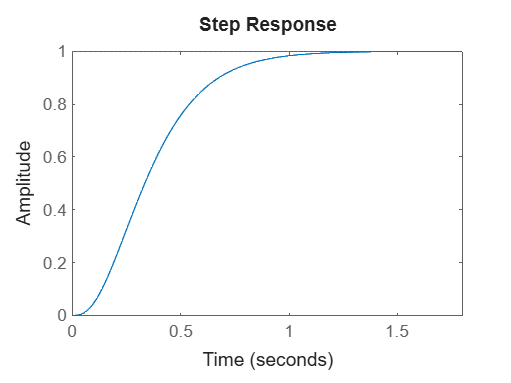


step(c * w)

stepinfo(c * w)

ans = struct with fields:
         RiseTime: 0.5397
    TransientTime: 0.9687
     SettlingTime: 0.9687
      SettlingMin: 0.9037
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 1.9879



tulvezerles = 1 / 0.1 / dcgain(w)

tulvezerles = 27.0000

**Válasz:** 

tulvezerles = 27

### **2. feladat **– 8 p

**Határozza meg az alábbi ábrán látható sorosan kapcsolt W1(s) és W2(s) rendszerek P(s) eredő átviteli függvényét. Ezután ezt csatolja mereven, negatívan vissza, és határozza meg az így kapott zárt hurkú rendszer T(s) átviteli függvényét.**

**Hasonlítsa össze az P(s) és a T(s) rendszereket a következők szerint: egységugrás bemenet esetén beállási idő és állandósult statikus hiba. Ez utóbbit analitikusan is számítsa ki mindkét esetben az eredő átviteli tényező illetve a körerősítés meghatározásával!**

$W_1 \left(s\right)=\frac{1}{8s+1}$, $W_2 \left(s\right)=\frac{4}{0\ldotp 25s+1}$

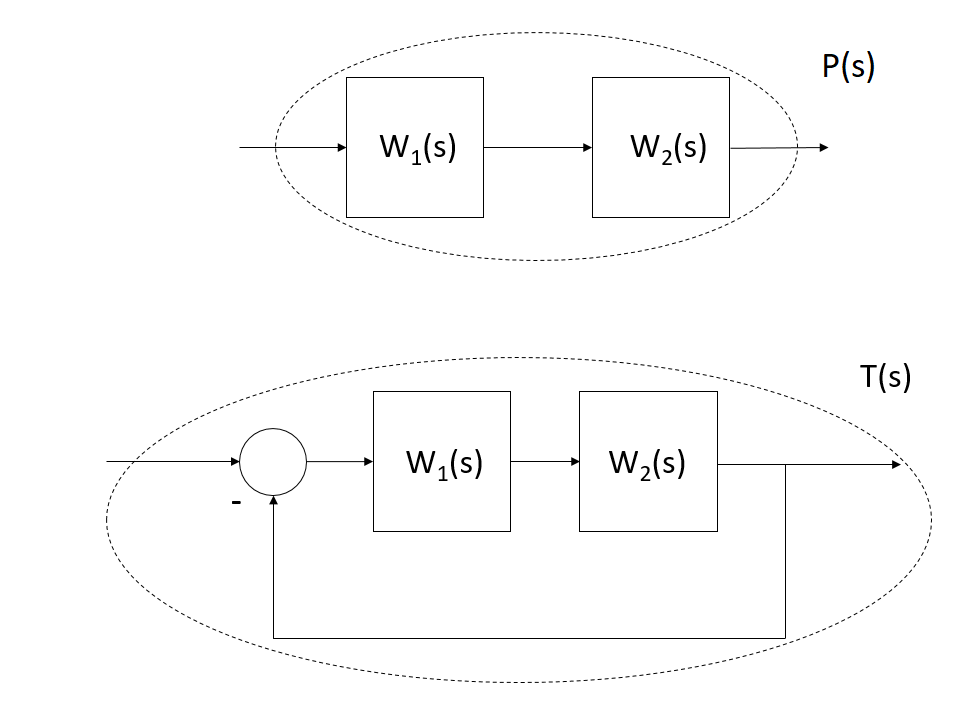

w1 = 1 / (8 * s + 1)


w1 =
 
    0.125
  ---------
  (s+0.125)
 
Continuous-time zero/pole/gain model.
Model Properties


w2 = 4 / (0.25 * s + 1)


w2 =
 
   16
  -----
  (s+4)
 
Continuous-time zero/pole/gain model.
Model Properties



p = w1 * w2


p =
 
         2
  ---------------
  (s+0.125) (s+4)
 
Continuous-time zero/pole/gain model.
Model Properties


t = feedback(p, 1)


t =
 
           2
  --------------------
  (s+0.7381) (s+3.387)
 
Continuous-time zero/pole/gain model.
Model Properties


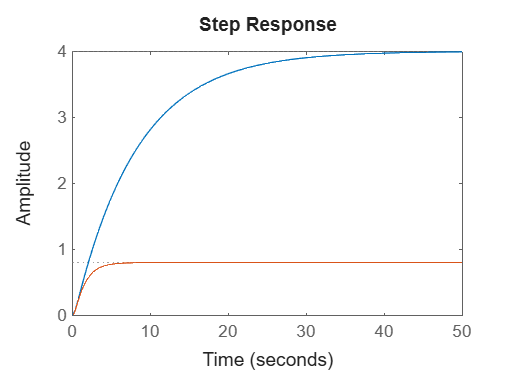


step(p, t)


estat_t = 1 - dcgain(t)

estat_t = 0.2000

estat_p = 1 - dcgain(p)

estat_p = -3


stepinfo(p)

ans = struct with fields:
         RiseTime: 17.5832
    TransientTime: 31.5521
     SettlingTime: 31.5521
      SettlingMin: 3.6057
      SettlingMax: 3.9973
        Overshoot: 0
       Undershoot: 0
             Peak: 3.9973
         PeakTime: 58.5778


stepinfo(t)

ans = struct with fields:
         RiseTime: 3.0970
    TransientTime: 5.6328
     SettlingTime: 5.6328
      SettlingMin: 0.7201
      SettlingMax: 0.7998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7998
         PeakTime: 11.3945



k = dcgain(p)

k = 4

estat_pa = 1 - k

estat_pa = -3

estat_ta = 1 / (1 + k)

estat_ta = 0.2000

**Válasz:** 

allandosult hiba: P rendszer eseteben: -3

allandosult hiba: T rendszer eseteben: 0.2000

`be allasi ido P rendszer - 31.5`

`be allasi ido P rendszer - 5.6`

### **3. feladat **– 10 p

**Készítse el a 2. feladatban kapott P(s) rendszer hiba alapú szabályzását az alább megadott C(s) szabályzóval:**

$C\left(s\right)=\frac{8s+1}{s}$.

**Ezután tegyük fel, hogy egy egységugrással gerjesztett, Pn(s) átviteli függvénnyel jellemezhető rendszer zavaró hatása a szimuláció során a 5. és 9. másodperc között hozzáadódik a kimenő jelhez. Tervezzen egy zavarkompenzációs előrecsatoló ágat, mellyel a teljes rendszer egységugrásra adott válasza a zavar időtartama alatt sem módosul 10%-nál nagyobb értékkel. Adja meg a tervezett Cn(s) kompenzációs tag átviteli függvényét. Csatoljon képet a SIMULINK modellről és mutassa meg a zavarelhárító szabályzó működését!**

$P_n \left(s\right)=\frac{0\ldotp 35}{0\ldotp 85s+1}$.

 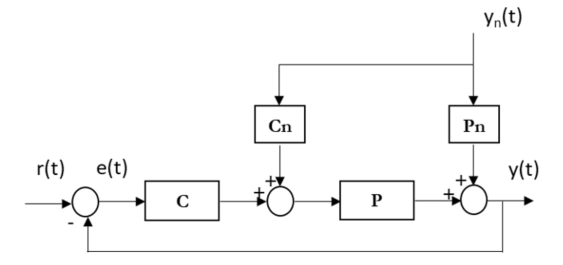

c = (8 * s + 1) / s


c =
 
  8 (s+0.125)
  -----------
       s
 
Continuous-time zero/pole/gain model.
Model Properties


pn = 0.35 / (0.85 * s + 1)


pn =
 
   0.41176
  ---------
  (s+1.176)
 
Continuous-time zero/pole/gain model.
Model Properties


cn = -pn / p /(0.1 * s + 1)


cn =
 
  -2.0588 (s+0.125) (s+4)
  -----------------------
     (s+1.176) (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties


**Válasz:** 

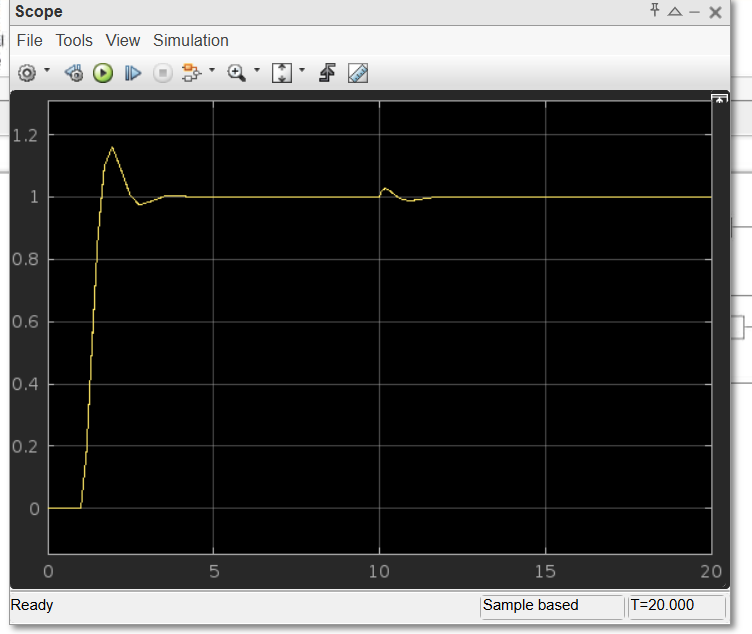

### **4. feladat **– 17 p

**a) Egy SISO LTI rendszer H(s) átviteli függvénye alább látható. Készítsen hiba alapú szabályzást a rendszer merev visszacsatolásával! Tervezzen az előrevezető ágba  a rendszer elé egy soros *****K***** erősítőt és vizsgálja meg a gyökhelygörbén, mely *****K***** értékekre stabil a zárt rendszer? Ábrázolja a gyökhelygörbét! A stabilitás határhelyzetében mekkora a tényleges körerősítés?**


$$H\left(s\right)=\frac{14}{12s^3 +42s^2 +39s+8}$$


h = 14 / ((s^3 * 12) + (s^2 * 42) + (s * 39) + 8)


h =
 
             1.1667
  -----------------------------
  (s+0.286) (s+1.105) (s+2.109)
 
Continuous-time zero/pole/gain model.
Model Properties


h = minreal(h)


h =
 
             1.1667
  -----------------------------
  (s+0.286) (s+1.105) (s+2.109)
 
Continuous-time zero/pole/gain model.
Model Properties


t = feedback(h, 1)


t =
 
               1.1667
  ---------------------------------
  (s+2.491) (s^2 + 1.009s + 0.7361)
 
Continuous-time zero/pole/gain model.
Model Properties


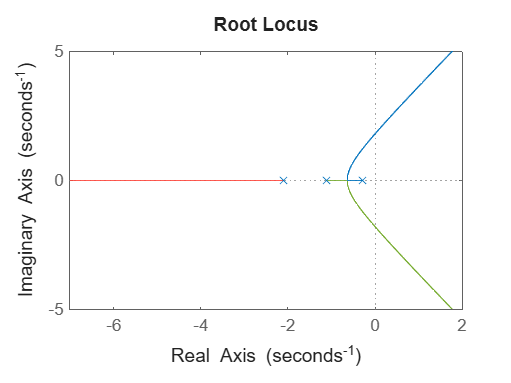


rlocus(h)

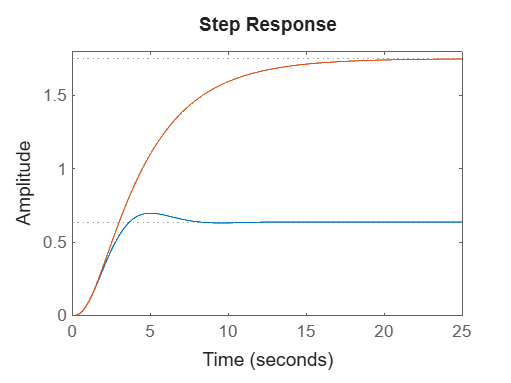


step(t, h)


[gm pm wg wc] = margin(h)

gm = 9.1796

pm = 99.2702

wg = 1.8029

wc = 0.3698


Kkrit = gm;
Kkorkrit = Kkrit * dcgain(h)

Kkorkrit = 16.0643

step(t, h)

**Válasz**: 

stabil: 0 - 9.09

**b) Adja meg a K erősítési értékek azon tartományát, amely esetén a zárt rendszer viselkedése aperiodikus! Szemléltesse egy-egy átmeneti függvénnyel, amikor a zárt rendszer viselkedése periodikus, aperiodikus, illetve labilis. Adja meg az egyes esetekhez választott K értékeket is!**

k1 = 0.201

k1 = 0.2010

k2 = 2.2

k2 = 2.2000

k3 = 10

k3 = 10

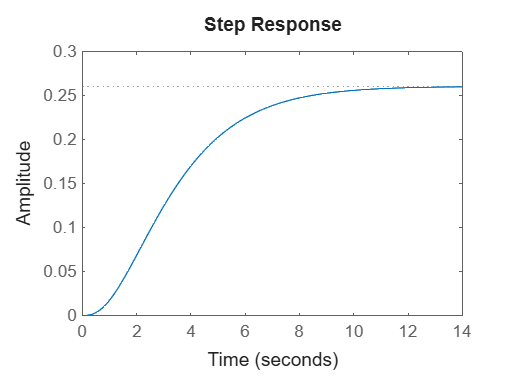


step(feedback(h * k1, 1))

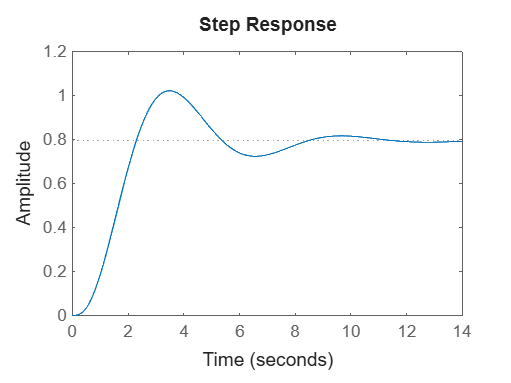

step(feedback(h * k2, 1))

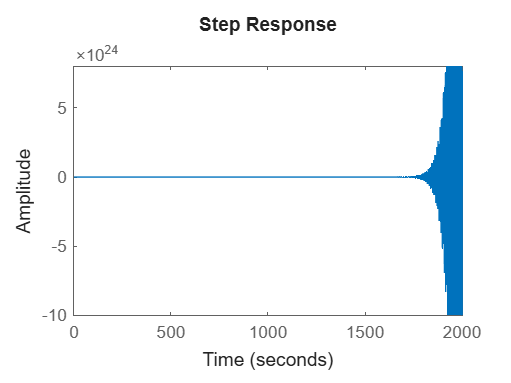

step(feedback(h * k3, 1))

**Válasz:** 

aperodikus - 0 -> 0.207

periodikus - 0.207 -> 9.09

instabil -  k >  9.09

**c) Adja meg a rendszer fázis- és késleltetési tartalékát! Demonstrálja a szállítási késés hatását azzal, hogy ábrázolja a zárt rendszer átmeneti függvényét a késleltetési tartaléknál kisebb, illetve nagyobb, a felnyitott körbe iktatott holtidő esetén! A vizsgálatok során legyen K=1.**

tmin = (pm * pi / 180) / wc 

tmin = 4.6847


l = h


l =
 
             1.1667
  -----------------------------
  (s+0.286) (s+1.105) (s+2.109)
 
Continuous-time zero/pole/gain model.
Model Properties


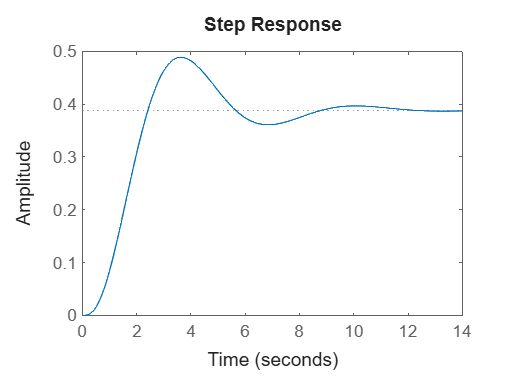

t = feedback(t,1);

step(t)

Ld1=l * exp(-4 * s)


Ld1 =
 
                         1.1667
  exp(-4*s) * -----------------------------
              (s+0.286) (s+1.105) (s+2.109)
 
Continuous-time zero/pole/gain model.
Model Properties


Ld2=l * exp(-6 * s)


Ld2 =
 
                         1.1667
  exp(-6*s) * -----------------------------
              (s+0.286) (s+1.105) (s+2.109)
 
Continuous-time zero/pole/gain model.
Model Properties


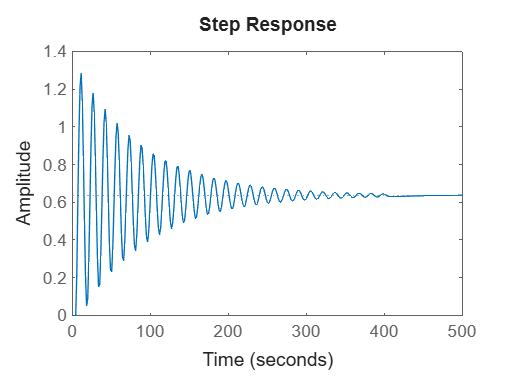


Td1 = feedback(Ld1,1);
Td2 = feedback(Ld2,1);

step(Td1)

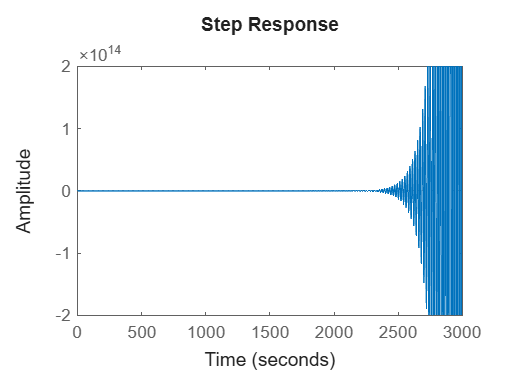

step(Td2)